# Defining Spectral Models

A fundamental part of Spectral Fitting Toolbox is the SpectralModel class. This class contains methods to perform both simulation and estimation for models defined by their spectral density function.

The minimum required to define such a model is the parametric spectral density function and a parameter vector.

The spectral density funtion must be a function that takes the parameter vector as its first argument, and a vector of angular frequencies as its second argument. It should return the spectral density function at these frequencies, and return partial derivatives and second-order partial derivatives as optional second and third outputs. For more information see the tutorial on defining custom models.

The parameter vector serves two purposes. Firstly, it acts as a true parameter when simulating from the model. Secondly, it acts as an initial value for optimisation algorithms used when fitting the model to data.

The user may also specify lower and upper bounds as optional third and fourth inputs. If they are not provided, then they are set to $-\infty$ and $\infty$ respectively and a warning will be displayed.

It is recommended that the lower and upper bounds are specified.

## Basic Model Definition

First note that to use the classes and function in Spectral Fitting Toolbox, you must use the namespace spectralFitting (this does not apply to methods used on objects that have been constructed).

To illustrate this, consider a model for wind-generated wave processes, given by a generalised JONSWAP function.

A function implementing this spectral density function is provided in the Spectral Fitting Toolbox, called genJONSWAPsdf.

sdf = @spectralFitting.genJONSWAPsdf;

We then define a parameter vector. The generalised JONSWAP has 4 parameters, so we choose an initial parameter vector $\theta$ to be

theta = [0.7;0.7;3.3;4];

We then define lower and upper bound vectors.

lb = [0;0;1;1];
ub = Inf(4,1);

Finally, the spectral model can be constructed by calling the constructor method.

waveSpecModel = spectralFitting.SpectralModel(sdf,theta,lb,ub);

## Properties

By displaying the model, we can see accessible properties.

display(waveSpecModel)

waveSpecModel =   SpectralModel with properties:

           spectralDensity: @spectralFitting.genJONSWAPsdf
            autoCovariance: []
    aliasedSpectralDensity: []
                lowerBound: [4×1 double]
                upperBound: [4×1 double]
                 parameter: [4×1 double]
                 hessIndex: [4×4 logical]
             nIntegralBins: 2048
            aliasTolerance: 1.000000000000000e-06
           objectiveMethod: 'debiasedWhittle'
           useDifferencing: 0
                fitRoutine: 'fminsearch'
        bartlettWindowSize: 128
            fminsearchOpts: [1×1 struct]
               fminconOpts: [1×1 optim.options.Fmincon]


spectralDensity stores the handle to the spectral density function.

autoCovariance is an optional property that stores the autoCovariance corresponding to the provided spectral density function. If this is not provided (because it is not known), then the autocovariance will be numerically approximated from the spectral density function.

aliasedSpectralDensity is similar to autoCovariance but is for the spectral density function of the process that results from sampling the continuous time process.

lowerBound and upperBound store the lower and upper bounds respectively.

parameter stores the parameter vector, in this case $\theta$.

hessIndex is a setting used by when fitting models to data. It can be left as default for most models, and is covered in more detail in the tutorial on advanced estimation.

nIntegralBins is the minimum number of bins used to approximate integrals numerically. By default this is set to 4096.

aliasTolerance is use to set a threshold for approaximating the aliased spectral density function. It is used to choose how the series should be truncated.

objectiveMethod is a string that indicates which objective function will be used to fit the model. This is discussed further in the tutorial on basic estimation.

useDifferencing is a flag that indicates if differencing should be used when fitting the model. By default it is set to false (no differencing will be used).

fitRoutine specifies the technique that is used to perform numerical optimisation as part of the fitting procedure. This is also discussed in the tutorial on basic estimation.

bartlettWindowSize is an option used by the bartlettLeastSquares fitRoutine. It specifies the size of the window used to construct the Bartlett periodogram.

fminsearchopts and fminconopts store optimisation options. It is recommended that these are not changed.

## Some Basic Methods

We start by specifying the sampling interval

Delta = 1;

To compute the spectral density function at a given omega vector, use

omega = [0,1,2,3];
dens = waveSpecModel.computeSpectralDensity(omega,Delta);

To compute the aliased spectral density function, use

aDens = waveSpecModel.computeAliasedSpectralDensity(omega,Delta);

To compute the autocovariance, we must specify the number of lags we are interested in, $N$. We the get the autocovariance at lags $0,\Delta,\ldots,(N-1)\Delta$.

N = 2048;
autoCov = waveSpecModel.computeAutoCovariance(N,Delta);

Finally to compute the expected periodogram, use

expI = waveSpecModel.computeExpectedPeriodogram(N,Delta);

The covariance and correlation of the periodogram can also be obtained by using

covI = waveSpecModel.computeCovPeriodogram(N,Delta);
corrI = waveSpecModel.computeCorrPeriodogram(N,Delta);

Note that if useDifferencing is set to be true, these methods will return the values for the differenced process (hence why $\Delta$ must be provided to computeSpectralDensity).

## Plotting

Similarly, plotting can be performed for each of the aforementioned methods. In addition, the frequency domain functions can be plotted on the decibel scale.

$N$ and $\Delta$ can be specified, but default to 1024 and 1 if they are not. Additional plotting arguments can be passed as normal.

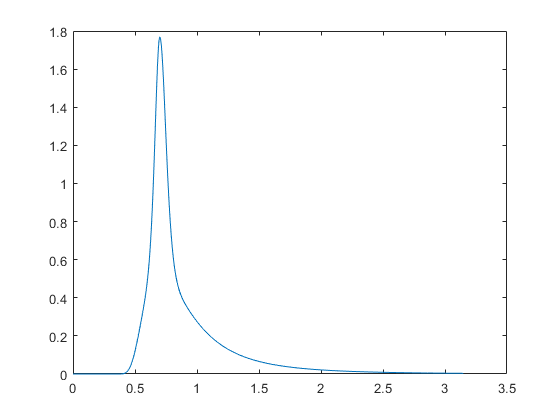

plotSdf(waveSpecModel)

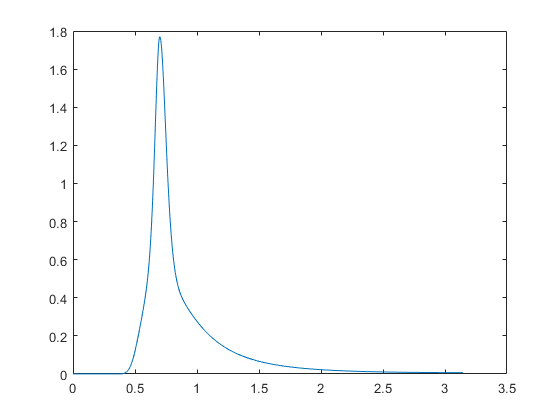

plotAliasedSdf(waveSpecModel,N,Delta)

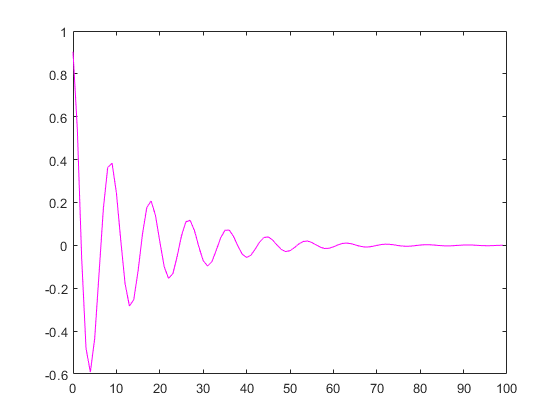

plotAcv(waveSpecModel,100,Delta,'color','m')

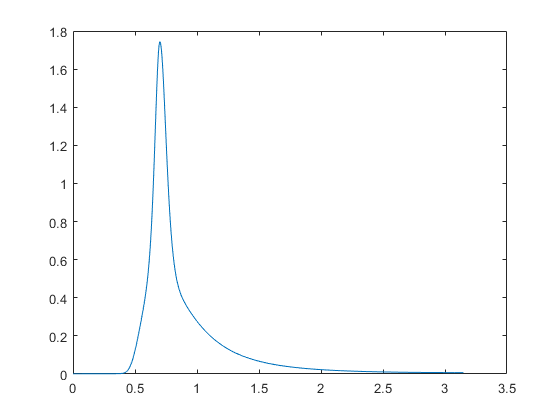

plotEI(waveSpecModel,1024,1)

To plot on the decibel scale, plotdB replaces plot as the prefix, i.e.

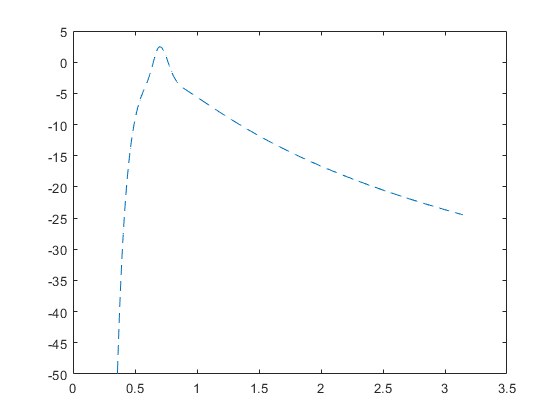

plotdBSdf(waveSpecModel,N,Delta,'linestyle','--'); 
ylim([-50,5]);

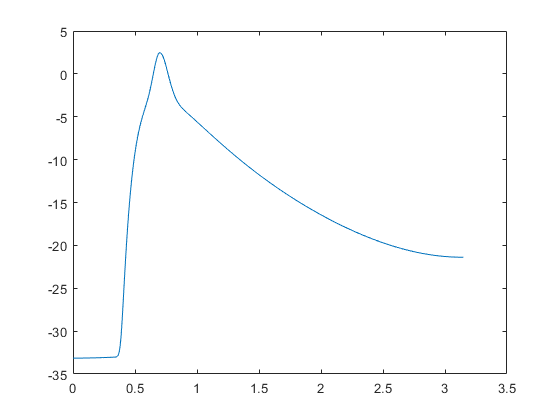


plotdBAliasedSdf(waveSpecModel)

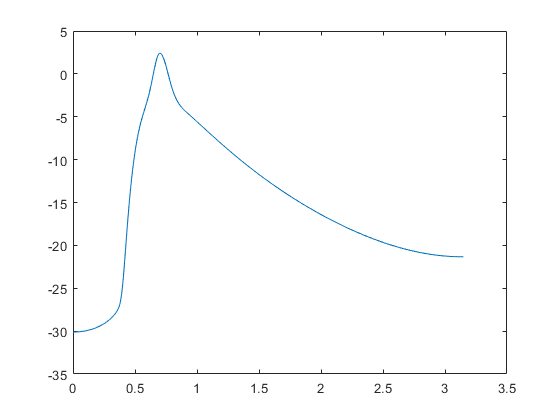

plotdBEI(waveSpecModel)